clc
clear
% path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\modelling\circle_videos\pixel_videos_directioned_Iqtau\';
% filename='large_fx_0.02_fy_0.05_fxy_0_tauc_0_xc_0_yc_0_freq_0.4_gray_nonAvgIqtau_angle_Iqtau.mat';
path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\real_videos_exp\cilia_videos_Analysis\';
filename='vidS1_nonAvgIqtau_angle_Iqtau.mat';
input=[path filename];
load(input)

angle_num=size(angle_Iqtau,1);
qVec=1:size(angle_Iqtau,2);
q_num=size(angle_Iqtau,2);
tVec=1:size(angle_Iqtau,3);
t_num=size(angle_Iqtau,3);

q_max=200;
figure()
plot3(repmat((qVec(1:q_max))',1,t_num),repmat((tVec),q_max,1),squeeze(angle_Iqtau(5,(1:q_max),:)))
% xlim([0 200])
xlabel('q')
ylabel('tau')
zlabel('Iqtau')
title('Direction 9')

wavelength=1;
scale=1024;
q_max=500;
plotIq_all_dirc_all_tau(filename,path,wavelength,scale,q_max)

tau=20;
plotIq_all_dirc_selected_tau(filename,tau,path,wavelength,scale,q_max)

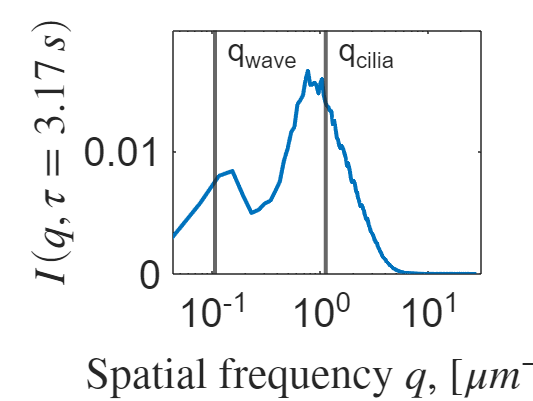

q_max = 723;
tau = 19;
fps = 30/5;
scale = 1024;
wavenumber = 27;

qVec=1:size(angle_Iqtau,2);
fig=figure();
y=sum(angle_Iqtau(:,1:q_max,tau),1);

% 6.9977
semilogx(qVec(1:q_max)*2*pi*6.2/scale,squeeze(y),"LineWidth",2)
% hxl = xline(wavenumber*6.9977/scale,'-',{'q_{cilia}, manually'},'LabelOrientation','horizontal','LineWidth',2);
% hxl = xline(0.15*2*pi,'-',{'q_{cilia}'},'LabelOrientation','horizontal','LineWidth',2);
hxl = xline(scale/35*2*pi*6.2/scale,'-',{'q_{cilia}'},'LabelOrientation','horizontal','LineWidth',2);
hxl.FontSize = 16;
% hxl = xline(wavenumber/scale,'-',{'q_{wave}, manually'},'LabelOrientation','horizontal','LineWidth',1);

hxl_g = xline(0.105,'-',{'q_{wave}'},'LabelOrientation','horizontal','LineWidth',2);
% hxl_g = xline(scale/1130*2*pi*6.2/scale,'-',{'q_{wave}'},'LabelOrientation','horizontal','LineWidth',2);
hxl_g.FontSize = 16;
%     ylim([0 1.2*max(y_avg)]);
ylim([0 1.2*max(y)]);
xlim([qVec(1)*2*pi*6.9977/scale qVec(q_max)*2*pi*6.9977/scale])
xticks([10^(-1) 10^(0) 10^(1)])
set(gca,'fontsize', 20); 

xlabel('Spatial frequency $q$, [$\mu m^{-1}$]','Interpreter','latex')
ylabel(['$I(q,\tau=$' num2str(round(tau/fps,2)) '$\,s)$'],'Interpreter','latex')

%     title(['Sum of all directions for \tau=' num2str(tau/10) 's'],'Interpreter','tex')


clf
t=19;
q_max=100;
for i=1:angle_num/4
    y=sum(angle_Iqtau(i:i+3,1:q_max,t));
    plot(qVec(1:q_max),y)
    hold on
end
legend
xlabel('q')
ylabel('Iqtau')
title('Iqtau-q in different directions')

figure()
clf
t=10;
q_max=100;
for i=1:angle_num
    y=angle_Iqtau(i,1:q_max,t);
    plot(qVec(1:q_max),y)
    hold on
end
legend
xlabel('q')
ylabel('Iqtau')
title('Iqtau-q in different directions')

figure()
bar(1:angle_num,squeeze(sum(sum(angle_Iqtau(:,10:100,:),2),3)));
xticks(1:angle_num)
xlabel('direction *pi/8')
ylabel('sum of Iqtau')
% ylim([0.00 1])
title('Sum of I(q=1:100,tau) in 8 directions')

figure()
q_max=120;
imagesc(squeeze(sum(angle_Iqtau(:,1:q_max,:),1)));
xticks([50 100 150])
xticklabels({'5','10','15'})
xlabel('lag time tau(s)')
ylabel('wavenumber q')
title('I(q,tau) heatmap')
colorbar;
set(gca,'fontsize', 12);

figure()
q=27;
plot(tVec/fps,squeeze(sum(angle_Iqtau(:,q,:),1)))
ylim([0 0.02])
xlabel('lag time tau(s)')
ylabel(['I(q=' num2str(q) ',tau)'])
title(['I(q=' num2str(q) ',tau)-tau plot'])
set(gca,'fontsize', 12);

figure()
q=3;
x=tVec/150;
y=squeeze(sum(angle_Iqtau(:,q,:),1));
exclude=[1 2];
% FT = fittype('x./210000 + k.*x.^n')
ft = fittype( 'fit_function(x,A,v,tau_c,B)' );
% StartPoint order: A,B,tau_c,v
f = fit( x(:), y, ft, 'StartPoint', [0.005, 0.005, -0.05, 4], 'Exclude', exclude)

f =      General model:
     f(x) = fit_function(x,A,v,tau_c,B)
     Coefficients (with 95% confidence bounds):
       A =    0.004358  (0.003603, 0.005114)
       B =     0.00582  (0.005657, 0.005984)
       tau_c =     -0.4768  (-0.5878, -0.3658)
       v =       4.367  (4.321, 4.414)

h=plot( f, x, y ,"o") 

h =   2×1 Line array:

  Line    (data)
  Line    (fitted curve)


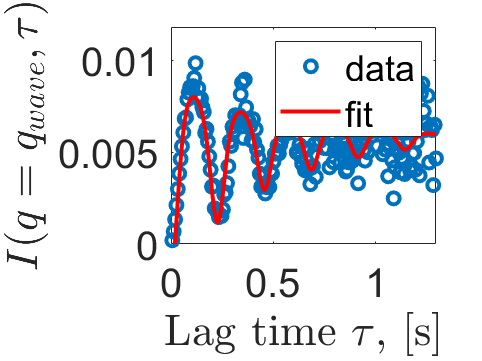

ylim([0 1.2*max(y)])
h(1).LineWidth=2;
h(2).LineWidth=2;
legend('data','fit')
xlabel('Lag time $\tau$, [s]','Interpreter','latex')
% ylabel(['$I(q=$' int2str(q) '$,\tau)$'],'Interpreter','latex')
ylabel(['$I(q=q_{wave},\tau)$'],'Interpreter','latex')
set(gca,'fontsize', 20); 

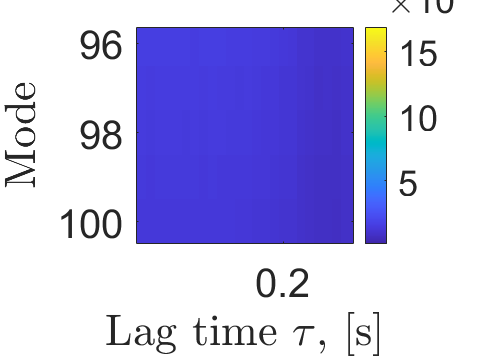

figure()
q_max=100;
tau_max=150;
imagesc(squeeze(sum(angle_Iqtau(:,1:q_max,1:tau_max),1)));
% Set x and y tick positions
x_ticks=[0,30,60,90,120,150];
xticks(x_ticks);
% yticks([0,5,10,15]);
axis square;

% Set x and y tick labels
% xticklabels({'0','1', '2', '3'});
xticklabels(round(x_ticks/150,2));
% yticklabels({'0', '5', '10', '15'});
xlabel('Lag time $\tau$, [s]','Interpreter','latex')
ylabel('Spatial frequency $q$, [$m^{-1}$]','Interpreter','latex')
ylabel('Mode','Interpreter','latex')
c = colorbar();
% c.Label.String = 'Intensity, [a.u.]';
c.Label.Interpreter = 'latex';
axis tight;
set(gca,'fontsize', 20);

path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\real_videos_exp\cilia_videos_Analysis\';
filename='vidS1_nonAvgIqtau.mat';
input=[path filename];
load(input);

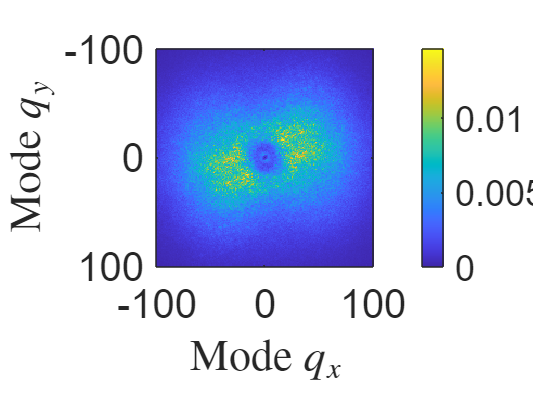

theta=0;
wavenumber=3;
scale=1024;
q_range=100;
tau=5;
plotFFTdifference(nonAvgIqtau,theta,wavenumber,scale,q_range,tau,path)

q=3;
x=tVec/30/5;
y=squeeze(sum(angle_Iqtau(:,q,:),1));
exclude=[1 2];
% FT = fittype('x./210000 + k.*x.^n')
ft = fittype( 'fit_function(x,A,v,tau_c,B)' );
% StartPoint order: A,B,tau_c,v
f = fit( x(:), y, ft, 'StartPoint', [0.05, 0.01, -0.05, 4], 'Exclude', exclude)
h=plot( f, x, y ,"o") 
h(1).LineWidth=2;
h(2).LineWidth=2;
title(['I(q=' num2str(q) ',tau)-tau plot'])
xlabel('lag time tau(s)')
ylabel(['I(q=' num2str(q) ',tau)'])
legend('data','fit')
set(gca,'fontsize', 16);

coeffnames(ft)

figure()
subplot(3,1,1);
q=10;
plot(tVec/30/5,squeeze(sum(angle_Iqtau(:,q,:),1)))
% ylim([0 0.02])
xlabel('lag time tau(s)')
ylabel(['I(q=' num2str(q) ',tau)'])
title(['I(q'',tau)-tau plot'])
set(gca,'fontsize', 12);

subplot(3,1,2);
q=20;
plot(tVec/30/5,squeeze(sum(angle_Iqtau(:,q,:),1)))
% ylim([0 0.02])
xlabel('lag time tau(s)')
ylabel(['I(q=' num2str(q) ',tau)'])
% title(['I(q=' num2str(q) ',tau)-tau plot'])
set(gca,'fontsize', 12);

subplot(3,1,3);
q=30;
plot(tVec/30/5,squeeze(sum(angle_Iqtau(:,q,:),1)))
% ylim([0 0.02])
xlabel('lag time tau(s)')
ylabel(['I(q=' num2str(q) ',tau)'])
% title(['I(q=' num2str(q) ',tau)-tau plot'])
set(gca,'fontsize', 12);

q=3;
figure();
bar(1:angle_num,squeeze(sum(angle_Iqtau(:,q,:),3)));
xticks(1:angle_num)
xlabel('direction *pi/16')
ylabel('sum of Iqtau')
title(['Sum of Iqtau(q=' num2str(q) ') in 16 directions'])

path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\real_videos_exp\cilia_videos_Analysis\';
filename='vidS1_nonAvgIqtau.mat';
input=[path filename];
wavenumber=0;
scale=1024;
q_range=100;
tau=37;
theta=0;
plotFFTdifference(input,theta,wavenumber,scale,q_range,tau,path)

% x_label=(0:angle_num-1)*180/angle_num
% strsplit(num2str(round(x_label)))
% set(gca,'xticklabel',{'40 feet','60 feet','120 feet'})

figure()
bar(1:angle_num,squeeze(sum(sum(angle_Iqtau,2),3)));

figure()
plot(1:t_num,squeeze(angle_Iqtau(1,1,:)))

imagesc(log(squeeze(sum(angle_Iqtau(5,1:10,:),1))))

% filename='large_fx_0.02_fy_0.02_fxy_0_tauc_0_xc_0_yc_0_freq_0.4_gray_nonAvgIqtau_angle_Iqtau.mat';
% input=[path filename];
% angle_Iqtau0202=load(input);
% 
% filename='large_fx_0.02_fy_0.1_fxy_0_tauc_0_xc_0_yc_0_freq_0.4_gray_nonAvgIqtau_angle_Iqtau.mat';
% input=[path filename];
% angle_Iqtau0210=load(input);
% 
% filename='large_fx_0.02_fy_0_fxy_0_tauc_0_xc_0_yc_0_freq_0.4_gray_nonAvgIqtau_angle_Iqtau.mat';
% input=[path filename];
% angle_Iqtau0200=load(input);

% filename='large_fx_0_fy_0_fxy_0_tauc_0_xc_0_yc_0_freq_0.4_gray_nonAvgIqtau_angle_Iqtau.mat';
% input=[path filename];
% angle_Iqtau0000=load(input);

q_max=50;
figure()
z=sum(angle_Iqtau(1:16,(1:q_max),:),1);
plot3(repmat((qVec(1:q_max))',1,t_num),repmat((tVec),q_max,1),squeeze(z))
% xlim([0 200])
xlabel('q')
ylabel('tau')
zlabel('Iqtau')
title('Sum of all directions')

num_of_wave_on_diagonal=1.41;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)


path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\modelling\circle_videos\paper_videos\plots\'

q_max=100;
figure()
y=sum(sum(angle_Iqtau(1:16,(1:q_max),:),1),3)...
    -sum(sum(angle_Iqtau0000.angle_Iqtau(1:16,(1:q_max),:),1),3);
plot(qVec(1:q_max),squeeze(y))
% xlim([0 200])
xlabel('q')
ylabel('Iqtau')
title('Sum of all directions, all taus')

figure()
t=30;
q_max_to_include=3;
q=17; % peak ]
subplot(4,1,1)
plot(1:angle_num,sum(angle_Iqtau0200.angle_Iqtau(:,1:q_max_to_include,t),2))
xlabel('direction')
ylabel('I(q=17,t=16)')
title('f_x=0.02, f_y=0')
subplot(4,1,2)
plot(1:angle_num,sum(angle_Iqtau0202.angle_Iqtau(:,1:q_max_to_include,t),2))
title('f_x=0.02, f_y=0.02')
subplot(4,1,3)
plot(1:angle_num,sum(angle_Iqtau(:,1:q_max_to_include,t),2))
title('f_x=0.02, f_y=0.05')
subplot(4,1,4)
plot(1:angle_num,sum(angle_Iqtau0210.angle_Iqtau(:,1:q_max_to_include,t),2))
title('f_x=0.02, f_y=0.10')
sgtitle('I in 16 different directions')

d=15;
q=2;
tVec=1:50;
fig=figure();
subplot(3,1,1)
plot(tVec/10,squeeze(angle_Iqtau02.angle_Iqtau(d,q,:)))
title('f_t=0.2Hz')
ylabel('I(q=2,t)')
subplot(3,1,2)
plot(tVec/10,squeeze(angle_Iqtau(d,q,:)))
title('f_t=0.4Hz')
ylabel('I(q=2,t)')
subplot(3,1,3)
plot(tVec/10,squeeze(angle_Iqtau06.angle_Iqtau(d,q,:)))
title('f_t=0.6Hz')
xlabel('time (s)')
ylabel('I(q=2,t)')
sgtitle('I(q=2,t)-t plot for different time frequencies')

saveas(fig,'I(q=2,t)-t plot for different time frequencies.png')

